Se eliminan las variables del espacio de trabajo y se cierran las ventanas de figuras abiertas para garantizar que los nuevos gráficos se generen sobre un entorno limpio.

%Limpieza de pantalla
clear all
close all
clc


Para construir polígonos, se discretiza el círculo unitario. La suavidad de la trayectoria depende exclusivamente del incremento (paso) asignado al parámetro t.

x(t)=cos(t),y(t)=sin(t)

Al utilizar π/2 o π/3, se conecta los puntos con líneas rectas, creando figuras geométricas cerradas.

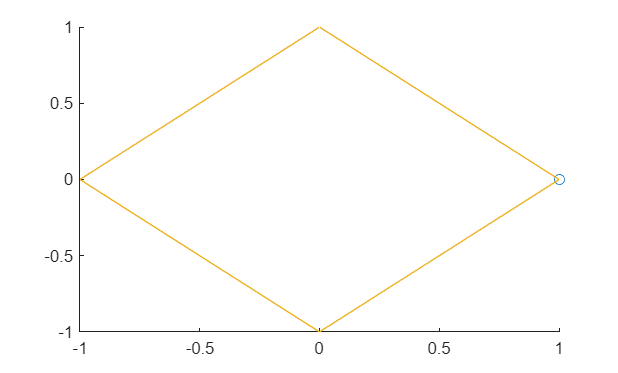

%Ejemplo 1**************************************************************
%Rombo

%Graficación de la trayectoria en coordenadas paramétricas

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t=0:pi/2:2*pi;

%Obtenemos las ecuaciones dependientes del tiempo
x=cos(t);
y=sin(t);

%graficamos la trayectoria
figure(1)
axis([-1 1 -1 1]); 
hold on;
comet(x,y)

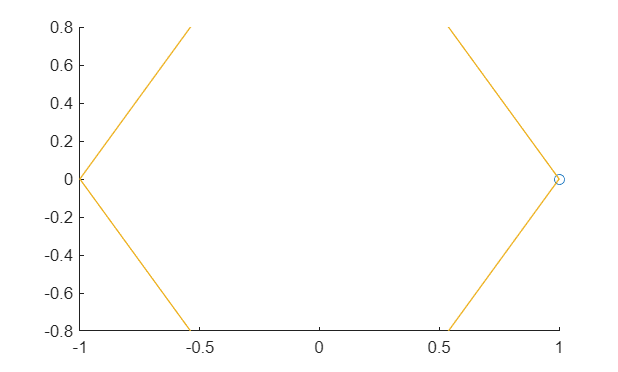



%Ejemplo 2**************************************************************
%Hexágono

%Graficación de la trayectoria en coordenadas paramétricas

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t2=0:pi/3:2*pi;

%Obtenemos las ecuaciones dependientes del tiempo
x2=cos(t2);
y2=sin(t2);

%graficamos la trayectoria
figure(2)
% Ajuste de eje de 1 a -0.8
axis([-1 1 -0.8 0.8]); 
hold on;
comet(x2,y2)

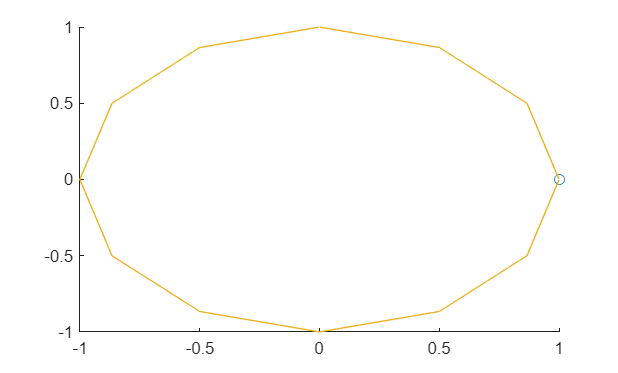



%Ejemplo 3**************************************************************
%Decágono / Dodecágono

%Graficación de la trayectoria en coordenadas paramétricas

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t3=0:pi/6:2*pi; % (Nota: pi/6 dibuja 12 lados para coincidir con tu imagen)

%Obtenemos las ecuaciones dependientes del tiempo
x3=cos(t3);
y3=sin(t3);

%graficamos la trayectoria
figure(3)
axis([-1 1 -1 1]); 
hold on;
comet(x3,y3)

Para generar figuras con pétalos, se introduce una variación en el radio de la trayectoria. Esto se logra multiplicando las funciones circulares por un coseno de mayor frecuencia. 

x(t)=A⋅cos(k⋅t)⋅cos(t)

y(t)=A⋅cos(k⋅t)⋅sin(t)

Donde:

**A**: Determina la escala o amplitud de la flor.

**k**: Controla la cantidad de pétalos. Si k es impar, la flor tiene exactamente k pétalos. Si k es par, la flor tiene 2k pétalos.

se utiliza un diferencial de tiempo muy pequeño (`0.01`) para que la trayectoria se observe continua y fluida.

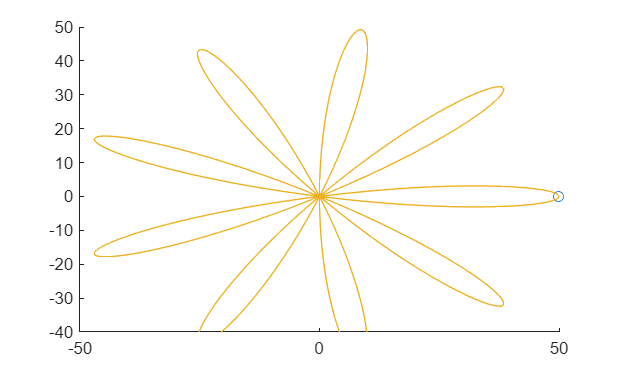

%Ejemplo 4**************************************************************
%Flor de 9 pétalos

%Graficación de la trayectoria en coordenadas paramétricas

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t4=[0:0.01:2*pi];

%Obtenemos las ecuaciones dependientes del tiempo
% Un factor impar (9) genera exactamente 9 pétalos
x4=50*cos(9*t4).*cos(t4);
y4=50*cos(9*t4).*sin(t4);

%graficamos la trayectoria
figure(4)
% Ajuste de eje de 50 a -40 en Y
axis([-50 50 -40 50]); 
hold on;
comet(x4,y4)

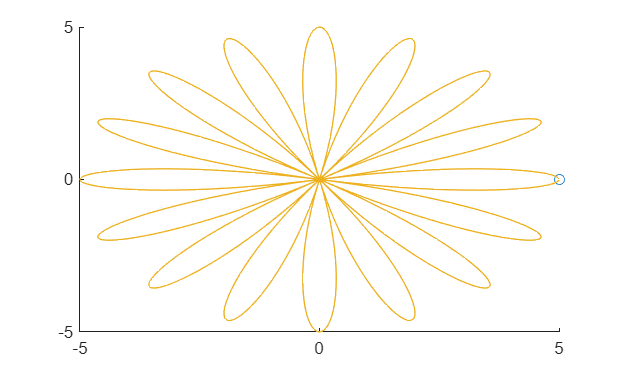



%Ejemplo 5**************************************************************
%Flor de 16 pétalos

%Graficación de la trayectoria en coordenadas paramétricas

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t5=[0:0.01:2*pi];

%Obtenemos las ecuaciones dependientes del tiempo
x5=5*cos(8*t5).*cos(t5);
y5=5*cos(8*t5).*sin(t5);

%graficamos la trayectoria
figure(5)
axis([-5 5 -5 5]); 
hold on;
comet(x5,y5)

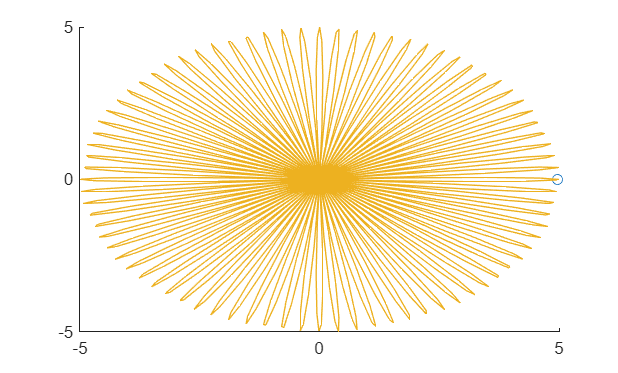



%Ejemplo 6**************************************************************
%Flor densa de muchos pétalos

%Graficación de la trayectoria en coordenadas paramétricas

%Se define el parámetro "t" de parametrización sobre el cual se realizará
%la proyección de trayectoria
t6=[0:0.01:2*pi];

%Obtenemos las ecuaciones dependientes del tiempo
x6=5*cos(40*t6).*cos(t6);
y6=5*cos(40*t6).*sin(t6);

%graficamos la trayectoria
figure(6)
axis([-5 5 -5 5]); 
hold on;
comet(x6,y6)